close all; 
clear;
clc;

syms taou

a1=0.9996;
a2=0.0020;
a3=0.000004;
b1=0.9987;
b2=-0.013;

p=5;
Trr=10:1:15;
Q=100;
R=1;
puc=0.003;
pvc=0.001;
% z1=R*taou.^2 + Q*exp((Trr(1) - (b2 + b1*pvc).^2 - (a2 + a1*puc + a3*taou).^2))
% z1=1000*exp(10-(0.000004*taou+0.005).^2) + 10*taou^2;
% J=exp(4-taou^2)+taou^2;
% dJ=diff(J);
% fun1 = @(taou) J;
% dfun1 = @(taou) dJ;
%  fun1 =@(taou) Q*exp((Trr(1) - (a2 + a1*puc + a3*taou)^2 - (b2 + b1*pvc)^2)) + Q*exp((Trr(round(p/2)) - (a1^round(p/2)*puc + (a2*(a1^round(p/2) - 1))/(a1 - 1) + (a3*taou*(a1^round(p/2) - 1))/(a1 - 1))^2 - (b1^round(p/2)*pvc + (b2*(b1^round(p/2) - 1))/(b1 - 1))^2)) + Q*exp((Trr(p) - (a1^p*puc + (a2*(a1^p - 1))/(a1 - 1) + (a3*taou*(a1^p - 1))/(a1 - 1))^2 - (b1^p*pvc + (b2*(b1^p - 1))/(b1 - 1))^2)) + 3*R*taou^2;
% dfun1 =@(taou) 6*R*taou - 2*Q*a3*exp((Trr(1) - (a2 + a1*puc + a3*taou)^2 - (b2 + b1*pvc)^2))*(a2 + a1*puc + a3*taou) - (2*Q*a3*exp((Trr(round(p/2)) - (a1^round(p/2)*puc + (a2*(a1^round(p/2) - 1))/(a1 - 1) + (a3*taou*(a1^round(p/2) - 1))/(a1 - 1))^2 - (b1^round(p/2)*pvc + (b2*(b1^round(p/2) - 1))/(b1 - 1))^2))*(a1^round(p/2) - 1)*(a1^round(p/2)*puc + (a2*(a1^round(p/2) - 1))/(a1 - 1) + (a3*taou*(a1^round(p/2) - 1))/(a1 - 1)))/(a1 - 1) - (2*Q*a3*exp((Trr(p) - (a1^p*puc + (a2*(a1^p - 1))/(a1 - 1) + (a3*taou*(a1^p - 1))/(a1 - 1))^2 - (b1^p*pvc + (b2*(b1^p - 1))/(b1 - 1))^2))*(a1^p - 1)*(a1^p*puc + (a2*(a1^p - 1))/(a1 - 1) + (a3*taou*(a1^p - 1))/(a1 - 1)))/(a1 - 1);


fun1 = R*taou^2 + Q*exp((Trr(1) - (b2 + b1*pvc)^2 - (a2 + a1*puc + a3*taou)^2));
dfun1 = 2*R*taou - 2*Q*a3*exp((Trr(1) - (b2 + b1*pvc)^2 - (a2 + a1*puc + a3*taou)^2))*(a2 + a1*puc + a3*taou);
fun2 = R*taou^2 + Q*exp((-Trr(1) +(b2 + b1*pvc)^2 + (a2 + a3*taou + a1*puc)^2));   
dfun2 = 2*R*taou + 2*Q*a3*exp((-Trr(1) +(b2 + b1*pvc)^2 + (a2 + a3*taou + a1*puc)^2))*(a2 + a3*taou + a1*puc); 

taou = 1*rand(1);
EPS = 0.00001;
px = 0.01;

a = eval(subs(fun1,taou));
b = a+1;
n = 1;
point(n,:) = [taou a];
while (abs(a-b) >= EPS) 
  if  Trr(1) >= ((b2 + b1*pvc)^2 + (a2 + a3*taou + a1*puc)^2)
  a = eval(subs(fun1,taou));
  taou = taou - px*eval(subs(dfun1,taou));
  b = eval(subs(fun1,taou)); 
  else
  a = eval(subs(fun2,taou));
  taou = taou - px*eval(subs(dfun2,taou));
  b = eval(subs(fun2,taou)); 
  end
  n = n+1;
  point(n,:) = [taou b]; 
end
taou

taou = 0.0593

n

n = 186

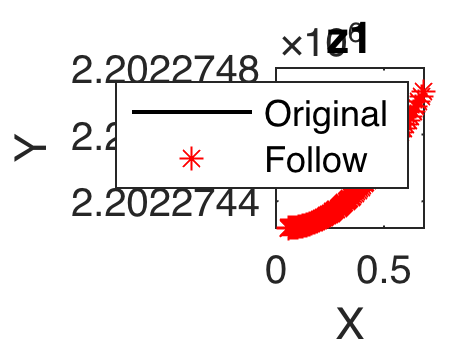

taou = -100:1:100;
% z1 = exp(4-taou.^2)+taou.^2;
z1 = Q*exp((Trr(1) - (a2 + a1*puc + a3*taou).^2 - (b2 + b1*pvc).^2)) + Q*exp((Trr(round(p/2)) - (a1.^round(p/2)*puc + (a2*(a1.^round(p/2) - 1))/(a1 - 1) + (a3*taou*(a1.^round(p/2) - 1))/(a1 - 1)).^2 - (b1.^round(p/2)*pvc + (b2*(b1.^round(p/2) - 1))/(b1 - 1)).^2)) + Q*exp((Trr(p) - (a1.^p*puc + (a2*(a1.^p - 1))/(a1 - 1) + (a3*taou*(a1.^p - 1))/(a1 - 1)).^2 - (b1.^p*pvc + (b2*(b1.^p - 1))/(b1 - 1)).^2)) + 3*R*taou.^2;
% z1=R*taou.^2 + Q*exp((Trr(1) - (b2 + b1*pvc).^2 - (a2 + a1*puc + a3*taou).^2));
% z1=1*exp(10-(100*taou).^2) + 0.0001*taou.^2;
figure
% plot(taou,z1)
% hold on
plot(point(:,1),point(:,2),'linewidth',1,'color','black')
hold on
scatter(point(:,1),point(:,2),'r','*');
axis on;xlabel('X');ylabel('Y');
title('z1')
legend('Original','Follow')